# **A lowpass digital filter’s specifications are given by: 𝜔s = 0.4𝜋 𝑟𝑎𝑑𝑖𝑎𝑛𝑠, 𝜔𝑝 = 0.25 𝑟𝑎𝑑𝑖𝑎𝑛𝑠, 𝐴𝑠 = 50 𝑑𝐵, 𝐴𝑝 = 0.25 𝑑𝐵**

% Digital Filter Specifications:
wp = 0.25*pi; % digital Passband freq
ws = 0.4*pi; % digital Stopband freq
Ap = 0.25; % Passband ripple in dB
As = 50; % Stopband attenuation in dB

Td = 1;

#### **a. Using an impulse invariance approach, find H(z) that satisfies the above specifications with monotonic passband and stopband.**

Design the analog lowpass filter Hc(s).

[N,Omegac] = buttord(wp,ws,Ap,As,'s')

N = 16

Omegac = 0.8769

[C,D] = butter(N,Omegac,'s')

C =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.1223


D =     1.0000    8.9466   40.0208  118.5757  260.0165  446.8788  622.0719  714.9710  685.4074  549.8046  367.8583  203.2122   90.9245   31.8857    8.2757    1.4226    0.1223


We obtain the desired digital filter H(z) = B(z)/A(z) using the coefficients in the arrays B and A.

[B,A] = impinvar(C,D,1/Td)

B = 	1.0e+-3 *

   -0.0000    0.0001   -0.0004    0.0011    0.0059    0.0743    0.2731    0.4704    0.3835    0.1549    0.0296    0.0026    0.0001    0.0000   -0.0000    0.0000         0


A =     1.0000   -7.4315   27.1507  -64.1755  109.2091 -141.2721  143.2320 -115.7981   75.2831  -39.4177   16.5414   -5.4977    1.4170   -0.2736    0.0373   -0.0032    0.0001


#### **b. Provide design plots in the form of log-magnitude, phase, group-delay, and impulse responses.**

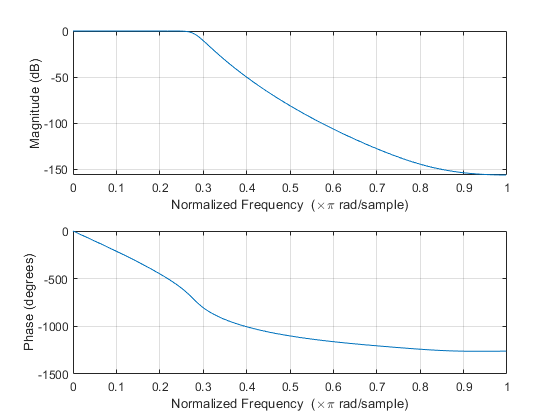

freqz(B,A)

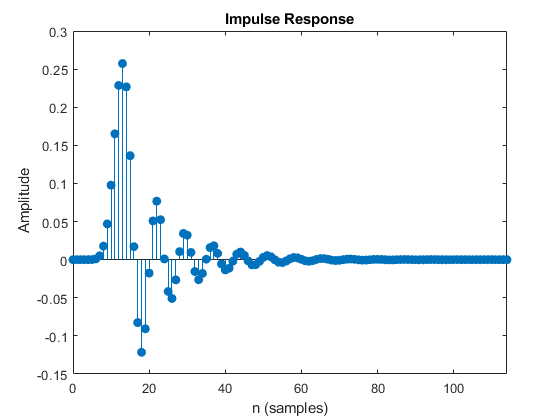

impz(B,A)

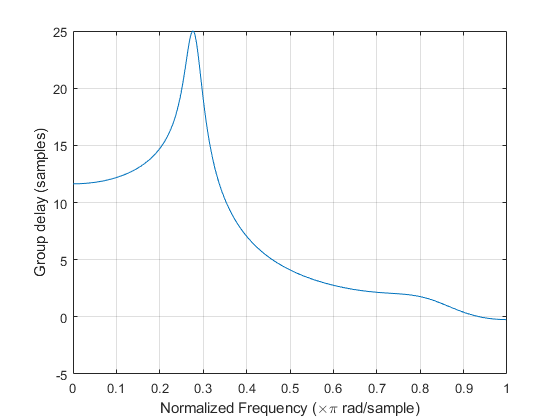

grpdelay(B,A)

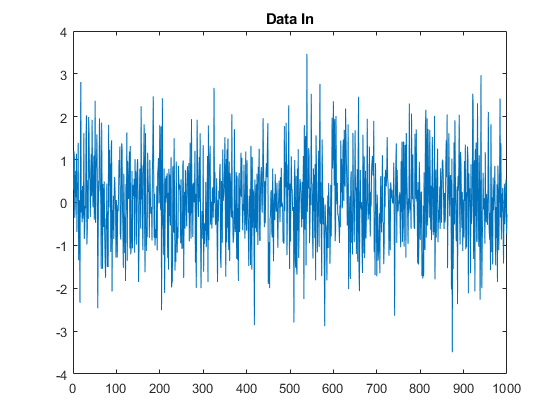

dataIn = randn(100,1);
dataOut = filter(B,A,dataIn);
plot(dataIn)
title('Data In')

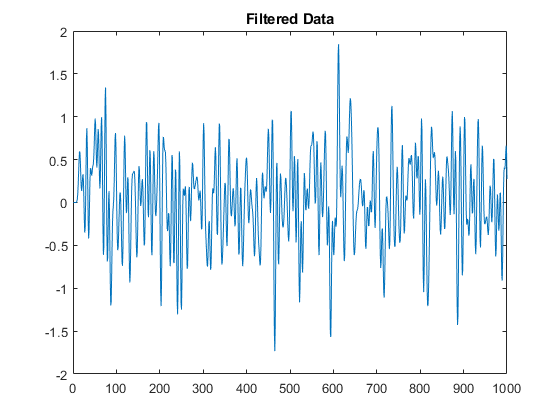

plot(dataOut)
title("Filtered Data")